# Análisis estructural y de estrés a modelos tridimensionales 

## **Materia: Análisis por Elemento Finito**

### **Profesor: José Isaac Sánchez Guerra**

### **Alumnos: **

- **Natalia de los Ángeles Sánchez Patiño**

- **Mario Rosas Otero**

### **Licenciatura en Tecnología, FESC, UNAM.**

**¿Qué es el análisis por elemento finito (FEA) por sus siglas en inglés?**

- El método de elemento finito, es una técnica numérica, para encontrar soluciones aproximadas a problemas con valores de frontera, para ecuaciones diferenciales parciales. 

- El método de elemento finito, busca dividir un problema complejo, en elementos más simples y pequeños que permiten plantear soluciones mas fácilmente, creando relaciones entre ellos. Matemáticamente se puede ver como la discretización de un fenómeno o cuerpo. 

- El método de elemento finito es útil para geometrías complicadas, cargas, y propiedades de materiales donde soluciones analíticas no se pueden obtener. 

**¿Cómo funciona el Análisis por Elemento Finito?**

- En el Análisis por Elemento Finito se utiliza un sistema complejo de puntos a los que se denomina como **nodos **que forman una cuadricula llamada malla. Esta **malla** se programa para contener las propiedades estructurales que definen como la estructura reaccionará a ciertas condiciones.

- Los nodos se asignan a una densidad a través del material dependiendo en los **niveles de estrés **anticipados en una área en específico.

- Las regiones que recibirán grandes cantidades de estres susualmente tienen grandes cantidades de nodos, que otras regiones que experimentan menos estres.Los puntos de interés pueden consistir de: puntos de fractura en materiales previemente probados, esquinas, filetes, detalles complejos y zonas de alto estrés.

- La malla actúa como una telaraña que en cada nodo extiende lazos con sus nodos adyacente. Esta red de vectores es la que contiene las propiedades del material, y la lleva al objeto, creando las particiones del elemento en subelementos. 

**Tipos de Análisis: **

- **Análisis estructural: **Consiste de modelos lineales y no lineales. Los modelos lineales utilizan parámetros simples y asumen que el material no se deforma plásticamente. Mientras que los modelos no lineales consisten en estresar el material mas allá de sus capacidades elásticas. El estrés en el material varía con la cantidad de deformación.

- **Análisis vibracional: **Es usado para probar un material contra vibraciones aleatorias, golpeteos, e impactos. Cada una de estas incidencias pueden actuar en la frecuencia de vibración natural de material, que podría ocasionar resonancia y un subsecuente fallo.

- **Análisis de fatiga: **Ayuda a los diseñadores a predecir la vida de un material o estructura mostrando los efectos de una carga cíclica en el espécimen. Este análisis puede mostrar las áreas, donde la propagación de la fisura es más probable que ocurra. Los fallos debido a la fatiga, pueden dañar también la tolerancia al material. 

- **Análisis de transferencia de calor: **modela la conductividad o dinámica de fluidez termal de un material o estructura. Puede consistir de un estado estático o de transferencia transitoria. La transferencia de estado estático refiere a las propiedades termales constantes en el material, que produce una difusión de calor lineal. 

**¿Como ayuda el análisis por elemento finito?**

- Es fácilmente aplicable a objetos complejos y de forma irregular compuestos por diferentes materiales y que tienen condiciones de frontera complejas. 

- Son aplicables a problemas de estado estático, dependientes del tiempo, y de valores propios (eigenvalores).

- Son aplicables a problemas lineales y no lineales

- Es un método que puede resolver una gran variedad de problemas incluyendo: problemas en mecánica de sólidos, mecánica de fluidos, reacciones químicas, electromagnetismo, biomecánica, transferencia de calor y acústica, entre otros. 

**Pasos del análisis por elemento finito:**

- Discretización

- Selección de funciones de aproximación

- Formación de la matriz de rigidez total

- Formación de la matriz de carga de elementos

- la formación de la ecuación de equilibrio general

- implementación de las condiciones de frontera

- Cálculo de los desplazamientos nodales desconocidos.

- Cálculo del estrés y tensión.

**Fases:**

- **Obtener geometría**

- **Preprocesamiento: **Así se genera la malla, divide la geometría dada en subdominios, aplica las propiedades del material y las condiciones de **frontera. **

- **Solución: **Se derivan las ecuaciones de la matriz y de genera la solución para las cantidades principales. 

- **Post-procesamiento: **Se verifica la validez de la solución generada, examinando los valores generados, como desplazamiento y estrés, y se retira los errores.

#### Ejercicios:

Esta serie de ejercicios se muestra cómo calcular la tensión térmica y la deformación de una llave española, una aspa de turbina de un avión, y una taza en su condición de funcionamiento en estado estacionario. Una llave española es sometida a estres estructural durante su uso cotidiano, por cual se vuelve interesante su análisis para la predicción de posibles quiebres bajo condiciones extremas en su uso. El aspa o hélice de turbina de avión tiene conductos de refrigeración interiores que ayudan a regular su temperatura, y manetenerla dentro de un limite para el materia del que esta compuesta. Una taza por su parte es sometida a altas temperaturas en su uso cotidiano. 

Los ejercicios realizados se realizan mediante un  un flujo de trabajo en tres pasos:

- Realizar el análisis estructural teniendo en cuenta únicamente presiones mecanicas o producidas por gases, segun el caso sobre los objetos estudiados

- Posteriormente se calcula la tensión térmica sin tener en cuenta la presión.

-  Por último se experimetna al combinar la presión y la tensión térmica.

# Carga de presión

#### Helice / Aspa

La helice experimenta una alta presión de los gases circundantes. Calcule la tensión causada sólo por esta presión. Primero, creamos un modelo estructural estático:

PAspa = createpde('structural','static-solid');

Importamos y trazamos la geometría, mostrando las etiquetas de las caras.

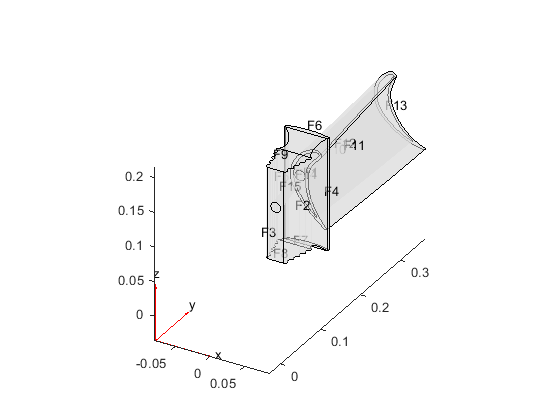

importGeometry(PAspa,'Blade.stl');
figure
pdegplot(PAspa,'FaceLabels','on','FaceAlpha',0.5)

Generamos una malla con el tamaño máximo de elemento 0.01.

malla = generateMesh(PAspa,'Hmax',0.01);

Especificamos el módulo de Young, la relación de Poisson y el coeficiente de expansión térmica para la aleación basada en níquel (NIMONIC 90)

E = 227E9; 
CTE = 12.7E-6; 
nu = 0.27; 

structuralProperties(PAspa,'YoungsModulus',E, ...
                            'PoissonsRatio',nu, ...
                            'CTE',CTE);

Especificamos que la cara de la raíz que está en contacto con otro metal es fija.

structuralBC(PAspa,'Face',3,'Constraint','fixed');

Especificamos la carga de presión en los lados de presión y succión de la pala. Esta presión se debe al gas de alta presión que rodea estos lados del aspa.

p1 = 5e5; 
p2 = 4.5e5; 

structuralBoundaryLoad(PAspa,'Face',11,'Pressure',p1);
structuralBoundaryLoad(PAspa,'Face',10,'Pressure',p2); 

Resolvemos el problema estructural.

Res1 = solve(PAspa);

Trazamos la tensión de von Mises y el desplazamiento. Especificamos un factor de escala de deformación de 100 para visualizar mejor la deformación.

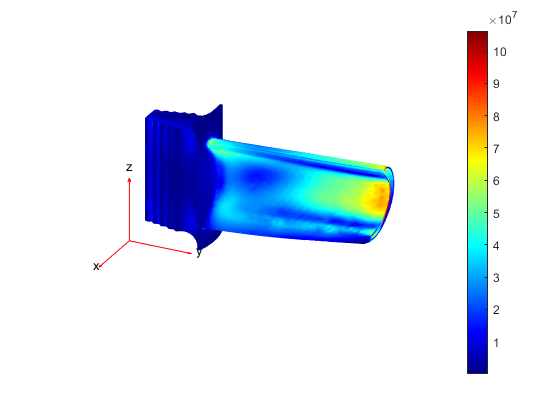

figure
pdeplot3D(PAspa,'ColorMapData',Res1.VonMisesStress, ...
                 'Deformation',Res1.Displacement, ...
                 'DeformationScaleFactor',100)
view([116,25])

La tensión máxima se sitúa en torno a los 100 Mpa, lo que está muy por debajo del límite elástico

**Llave Española:**

La llave experimenta presiones en tres de sus caras, las caras que entran en contacto directamente con la tuerca y el mango donde se aplica la fuerza. Calcule la tensión causada sólo por esta presión. Primero, creamos un modelo estructural estático:

PLlave = createpde('structural','static-solid');

Importamos y trazamos la geometría, mostrando las etiquetas de las caras.

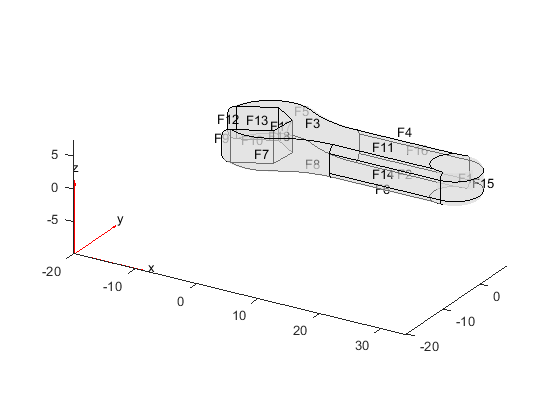

importGeometry(PLlave,'spanner.stl');
figure
pdegplot(PLlave,'FaceLabels','on','FaceAlpha',0.5)

Generamos una malla con el tamaño máximo de elemento 0.5.

malla_llave = generateMesh(PLlave,'Hmax',0.5);

Especificamos el módulo de Young, la relación de Poisson y el coeficiente de expansión térmica para el acero

E = 20E10; % en Pa
CTE = 35E-6; % in 1/K
nu = 0.3; 

structuralProperties(PLlave,'YoungsModulus',E, ...
                            'PoissonsRatio',nu, ...
                            'CTE',CTE);

Especificamos que la cara que está en contacto con otro metal es fija.

structuralBC(PLlave,'Face',17,'Constraint','fixed');

Especificamos la carga de presión en los lados de presión de la llave. Esta presión se debe a la fuerza aplicada a la llave para girar una tuerca.

p1 = 1e5; 
p2 = 1e5;
p3 = 1e5;

structuralBoundaryLoad(PLlave,'Face',16,'Pressure',p1);
structuralBoundaryLoad(PLlave,'Face',12,'Pressure',p2);
structuralBoundaryLoad(PLlave,'Face',13,'Pressure',p3);

Resolvemos el problema estructural.

Res2 = solve(PLlave);

Trazamos la tensión de von Mises y el desplazamiento. Especificamos un factor de escala de deformación de 100 para visualizar mejor la deformación.

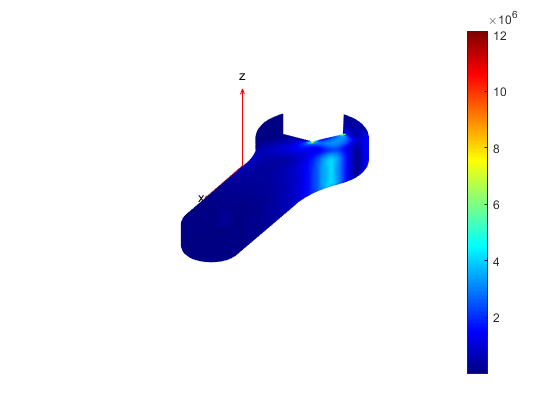

figure
pdeplot3D(PLlave,'ColorMapData',Res2.VonMisesStress, ...
                 'Deformation',Res2.Displacement, ...
                 'DeformationScaleFactor',100)
view([116,25])

La tensión máxima se sitúa en torno a los 100 Mpa, lo que está muy por debajo del límite elástico

# Tensión térmica

Determinamos la distribución de la temperatura y calcule la tensión y la deformación debidas únicamente a la expansión térmica. Esta parte del ejemplo ignora la presión.

En primer lugar, creamos un modelo térmico para el análisis térmico en estado estacionario.

TAspa = createpde('thermal','steadystate');

Importamos la misma geometría y utilice la misma malla que para el análisis estructural.

importGeometry(TAspa,'Blade.stl');
TAspa.Mesh = malla;

Asumiendo que la aspa está hecha de una aleación basada en níquel (NIMONIC 90), especifique la conductividad térmica.

kappa = 11.5; % in W/m/K
thermalProperties(TAspa,'ThermalConductivity',kappa);

La transferencia de calor por convección entre el fluido circundante y las caras del álabe define las condiciones de contorno para este problema. El coeficiente de convección es mayor donde la velocidad del gas es mayor. Además, la temperatura del gas es diferente alrededor de las distintas caras. La temperatura del aire de refrigeración interior es de 150 °C, mientras que la temperatura en las caras de presión y succión es de 1000 °C.

% Refrigeración interior
thermalBC(TAspa,'Face',[15 12 14], ...
                 'ConvectionCoefficient',30, ...
                 'AmbientTemperature',150);
% Lado de presión
thermalBC(TAspa,'Face',11, ...
                 'ConvectionCoefficient',50, ...
                 'AmbientTemperature',1000);
% Lado de succión
thermalBC(TAspa,'Face',10, ...
                 'ConvectionCoefficient',40, ...
                 'AmbientTemperature',1000);
% Punta
thermalBC(TAspa,'Face',13, ...
                 'ConvectionCoefficient',20, ... 
                 'AmbientTemperature',1000);
% Base (expuesta a gases calientes)
thermalBC(TAspa,'Face',1, ...
                 'ConvectionCoefficient',40, ...
                 'AmbientTemperature',800);
% Raíz en contacto con gases calientes
thermalBC(TAspa,'Face',[6 9 8 2 7], ...
                 'ConvectionCoefficient',15, ...
                 'AmbientTemperature',400);

La condición de contorno para las caras de la raíz en contacto con otro metal es un contacto térmico que puede ser modelado como convección con un coeficiente muy grande (alrededor de 1000 W/(m2K) para el contacto metal-metal).

% Raíz en contacto con metal
thermalBC(TAspa,'Face',[3 4 5], ...
                 'ConvectionCoefficient',1000, ...
                 'AmbientTemperature',300);

Resuelve el modelo térmico.

Res3 = solve(TAspa);

Trazamos la distribución de la temperatura. La temperatura entre la punta y la raíz oscila entre unos 820 °C y 330 °C. La temperatura exterior del gas es de 1000 °C. El enfriamiento interior es eficaz: disminuye considerablemente la temperatura.

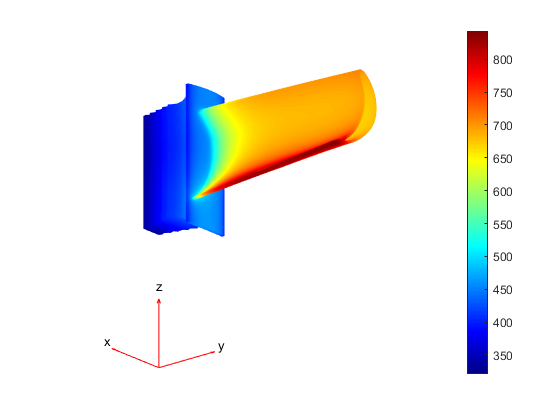

figure
pdeplot3D(TAspa,'ColorMapData',Res3.Temperature)
view([130,-20]);

Ahora, creamos un modelo estructural estático para calcular las tensiones y deformaciones debidas a la expansión térmica.

tPAspa = createpde('structural','static-solid');

Importamos la misma geometría y utilizamos la misma malla y propiedades estructurales del material que para el análisis estructural.

importGeometry(tPAspa,'Blade.stl');
tPAspa.Mesh = malla;
structuralProperties(tPAspa,'YoungsModulus',E, ...
                             'PoissonsRatio',nu, ...
                             'CTE',CTE);

Especificamos la temperatura de referencia.

tPAspa.ReferenceTemperature = 300; %en grados °C
structuralBodyLoad(tPAspa,'Temperature',Res3);

Especificamos la condición de contorno

structuralBC(tPAspa,'Face',3,'Constraint','fixed')

ans =   StructuralBC with properties:

                RegionType: 'Face'
                  RegionID: 3
                Vectorized: 'off'

   Boundary Constraints and Enforced Displacements
              Displacement: []
             XDisplacement: []
             YDisplacement: []
             ZDisplacement: []
                Constraint: "fixed"
                    Radius: []
                 Reference: []

   Boundary Loads
                     Force: []
           SurfaceTraction: []
                  Pressure: []
    TranslationalStiffness: []


Resolvemos el problema de la tensión térmica.

Res4 = solve(tPAspa);

Trazamos la tensión de von Mises y el desplazamiento. Especifique un factor de escala de deformación de 100 para visualizar mejor la deformación. La tensión se concentra en la raíz restringida porque no puede expandiRes1e libremente, y también en la unión entre la hoja y la raíz

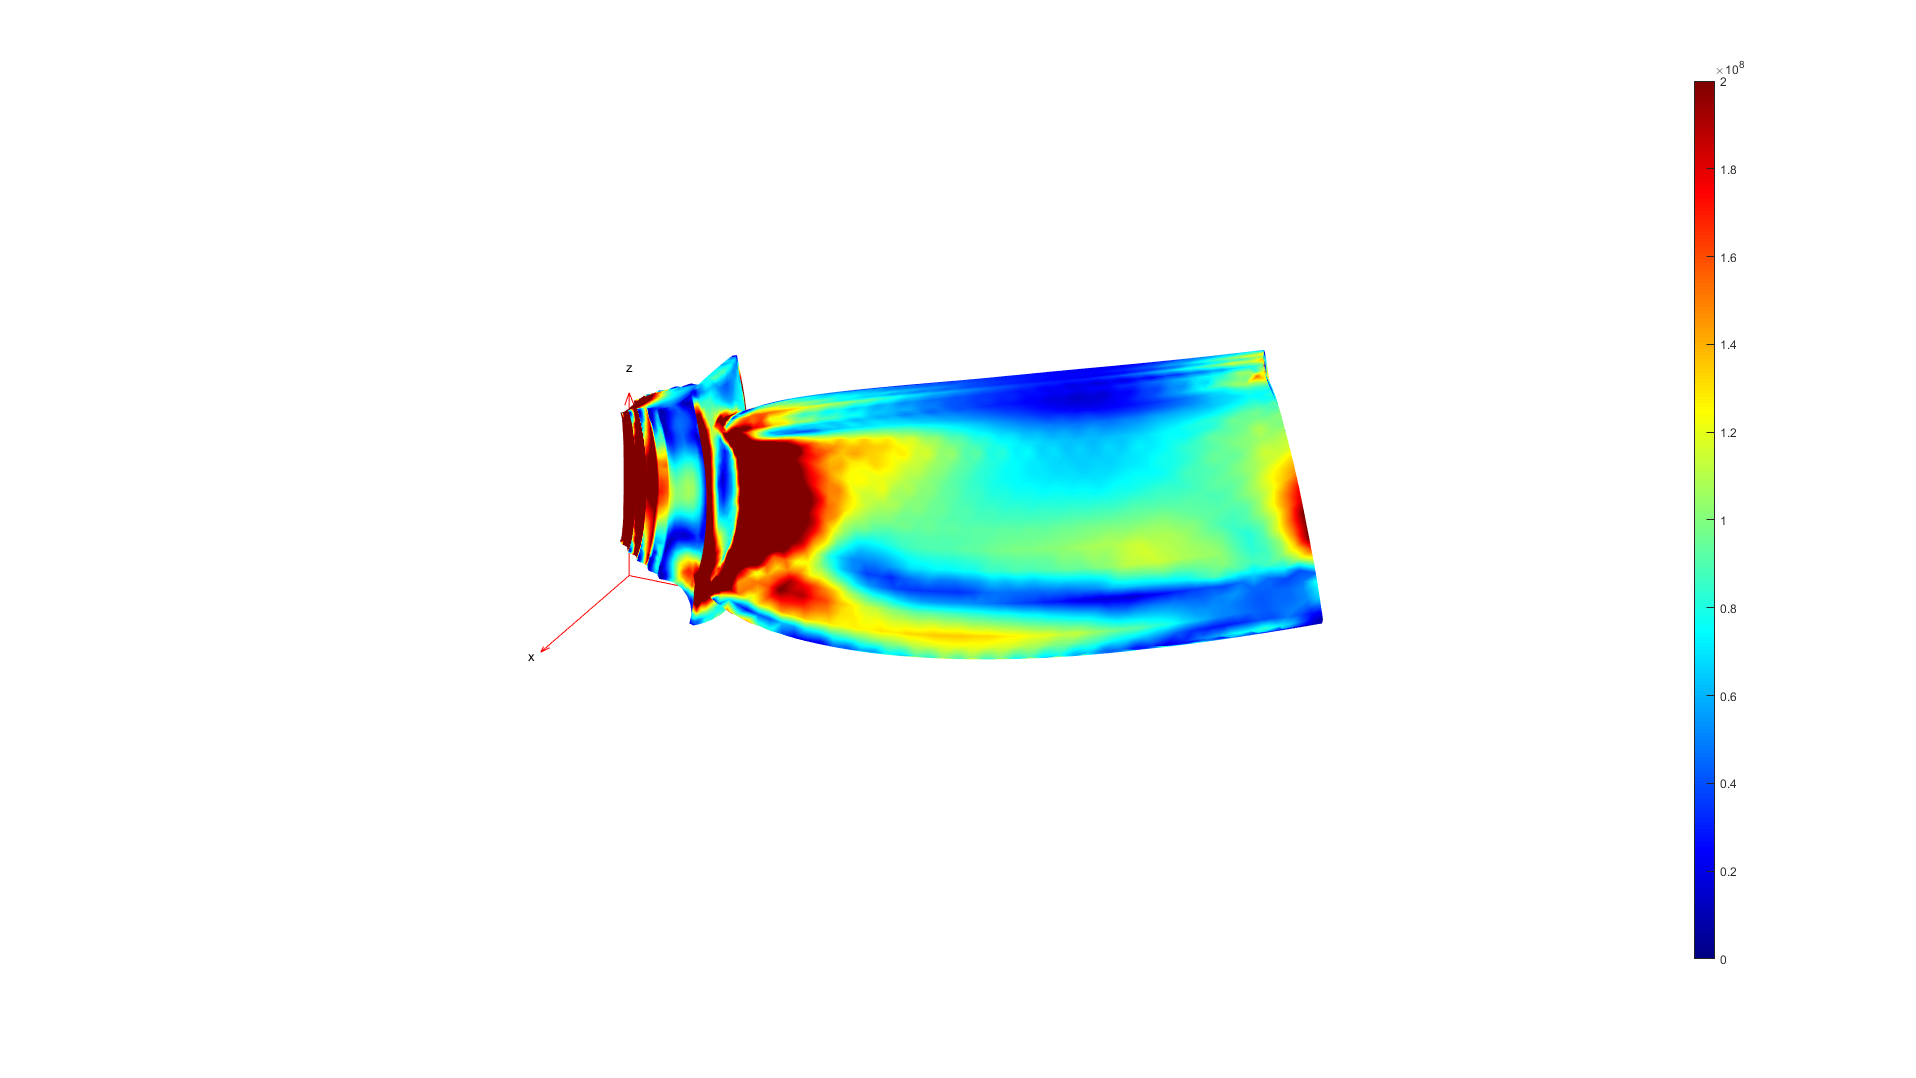

figure('units','normalized','outerposition',[0 0 1 1]);
pdeplot3D(tPAspa,'ColorMapData',Res4 .VonMisesStress, ...
                  'Deformation',Res4 .Displacement, ...
                  'DeformationScaleFactor',100)
caxis([0, 200e6])
view([116,25]);

Evaluamos el desplazamiento en la punta. En el diseño de la cubierta, este desplazamiento debe teneRes1e en cuenta para evitar la fricción entre la cubierta y el hélice.

max(Res4 .Displacement.Magnitude)

ans = 0.0042

Cargamos la combinación de presión y tensión térmica

Calculamos las tensiones y deformaciones causadas por la combinación de efectos térmicos y de presión.

Utilice el mismo modelo que para el análisis de la tensión térmica. Añadiendo la carga de presión en los lados de presión y succión del álabe. Esta presión se debe al gas de alta presión que rodea estos lados del hélice.

structuralBoundaryLoad(tPAspa,'Face',11,'Pressure',p1); % Lado de presión
structuralBoundaryLoad(tPAspa,'Face',10,'Pressure',p2);  % Lado de succión

Resuelviendo el modelo.

Res5 = solve(tPAspa);

Trazamos la tensión de von Mises y el desplazamiento. Especificandoun factor de escala de deformación de 100 para visualizar mejor la deformación.

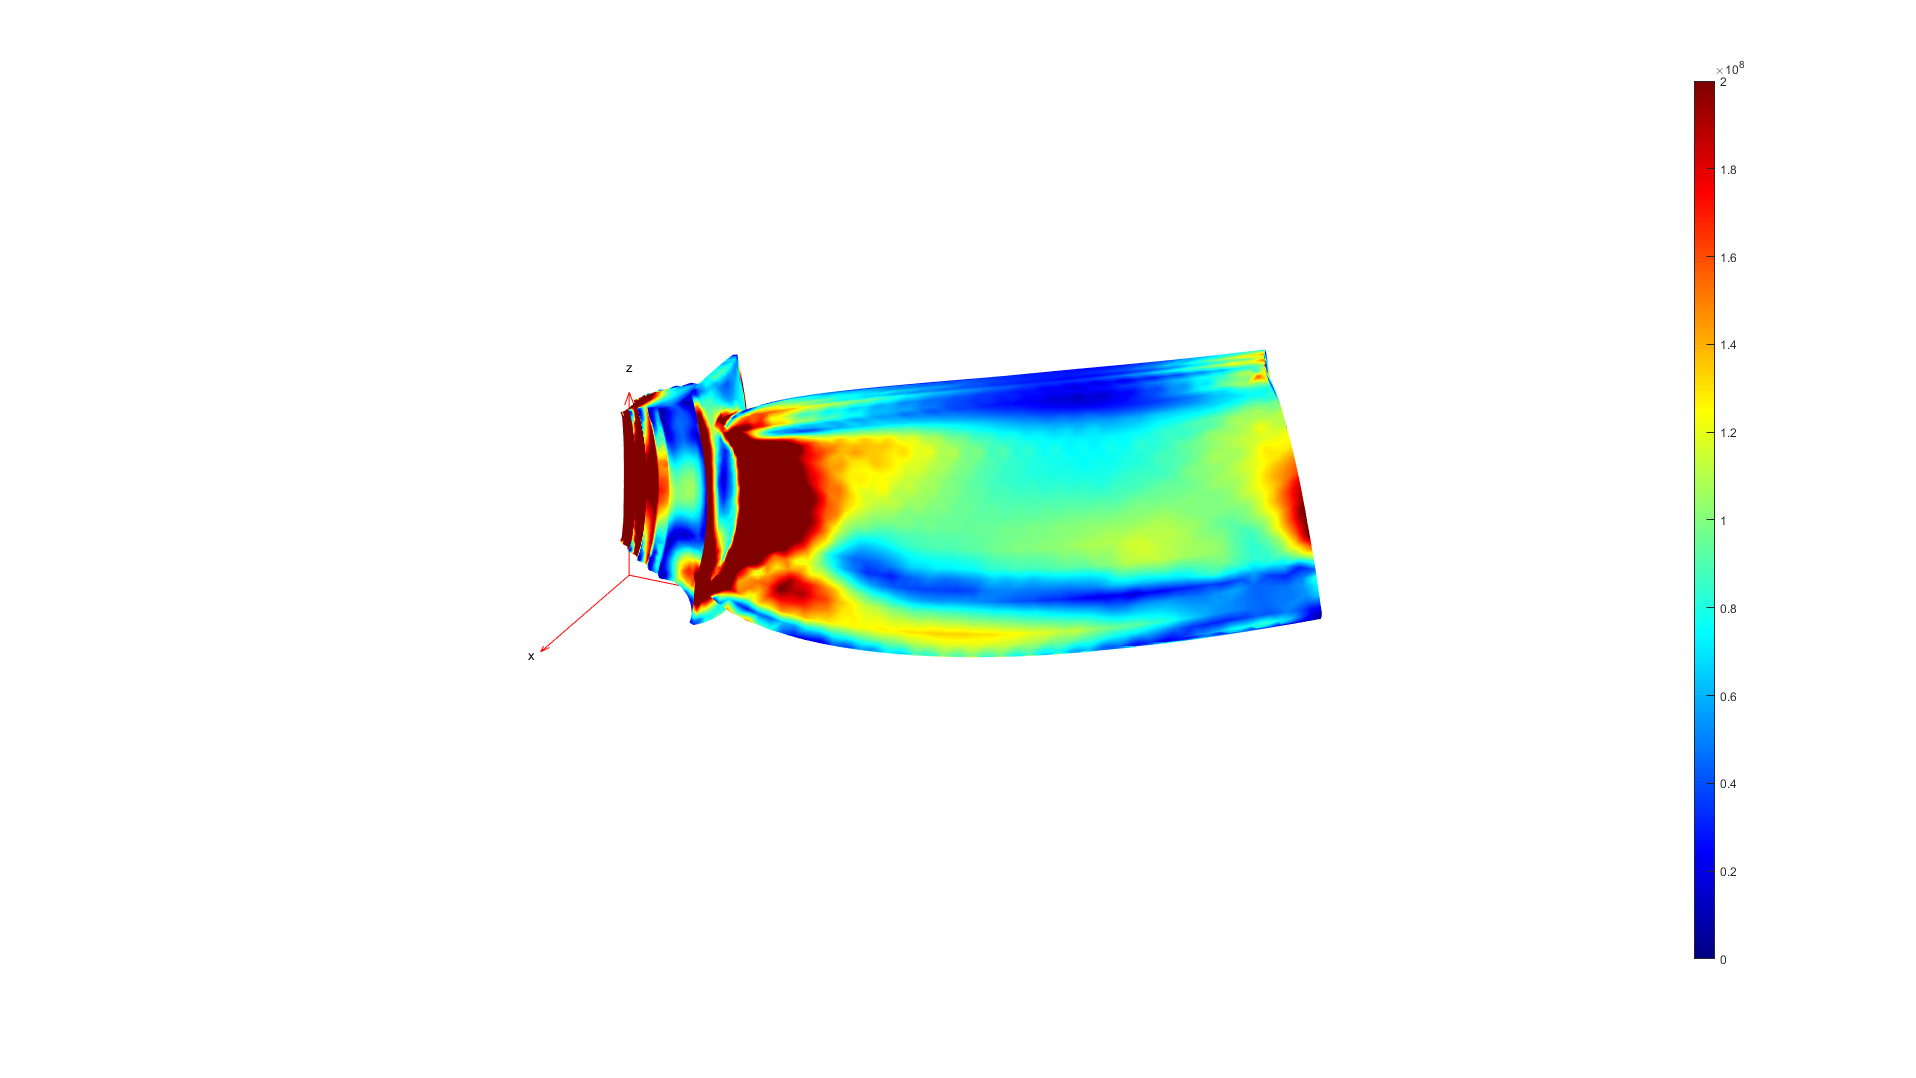

figure('units','normalized','outerposition',[0 0 1 1]);
pdeplot3D(tPAspa,'ColorMapData',Res5.VonMisesStress, ...
                  'Deformation',Res5.Displacement, ...
                  'DeformationScaleFactor',100)
caxis([0, 200e6])
view([116,25]);

Evaluamos la tensión máxima y el desplazamiento máximo. El desplazamiento es casi el mismo que para el análisis de la tensión térmica, mientras que la tensión máxima, 854 MPa, es significativamente mayor

max(Res5.VonMisesStress)

ans = 2.0746e+09

max(Res5.Displacement.Magnitude)

ans = 0.0042

## Análisis termal del cilindro

Importamos la geometria y la visualizamos

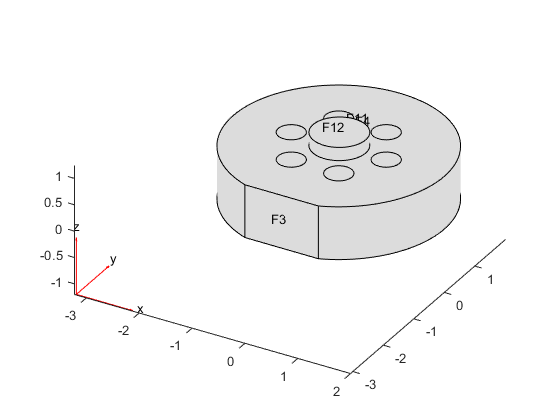

Cilindro = createpde(1); 
importGeometry(Cilindro,'cyl_6_0.9.STL');
figure
pdegplot(Cilindro,'FaceLabels','on');

Especificamos lo coeficientes de la ecuación diferencial, para la ecuación de Laplace, conducción de calor

c = 1e-1;
a = 0;
f = 0;

Especificamos las condiciones de frontera

Temperatura ambiente

TempAmb = 6;

Coeficiente de transferencia de calor

hc = 0.3;

Caras con condiciones de fontera

Lado = 1;
CarasCF = Cilindro.Geometry.NumFaces;

Aplicamos las condiciones de frontera

Cilindro.applyBoundaryCondition('Face',[Lado,CarasCF],...
    'q',hc,'g',TempAmb)

ans =   BoundaryCondition with properties:

           BCType: 'neumann'
       RegionType: 'Face'
         RegionID: [1 12]
                r: []
                h: []
                g: 6
                q: 0.3000
                u: []
    EquationIndex: []
       Vectorized: 'off'


Caras con fuente de calor 

CarasE = (4:11);

Aplicamos flujo unitario en als caras de la fuente de calor de entrada

Cilindro.applyBoundaryCondition('Face',CarasE,'g',1);

Generamos la malla

Cilindro.generateMesh('hmax',0.25);

Resolvemos

resultado = assempde(Cilindro,c,a,f);

Visualizamos

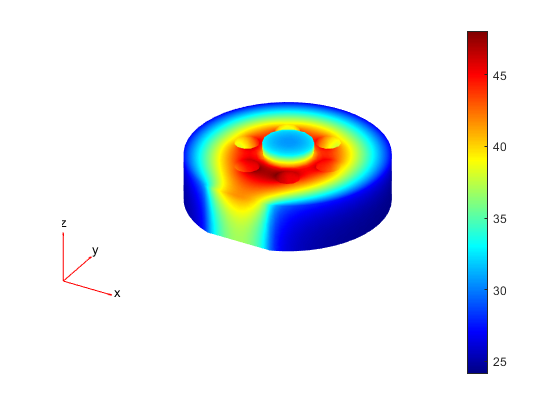

figure
pdeplot3D(Cilindro,'colormapdata',resultado);